% デフォルトの線の幅を設定
set(0,'DefaultLineLineWidth',1);

% デフォルトのフォント設定
fontsize = 16; % フォントサイズ
fontname = 'Helvetica'; % 使用フォント
set(0,'defaultAxesFontSize',fontsize);
set(0,'defaultTextFontSize',fontsize);
set(0,'defaultAxesFontName',fontname);
set(0,'defaultTextFontName', fontname);


x, y軸の設定


n = 8; % n列目
m = 9; % m列目
N = [n, m]

N =      8     9


c = 0.05

c = 0.0500

csvファイルの内容を確認

% ファイルのフルパスを取得
filePath = fullfile('csvPath')

filePath = '\Users\yuuju\Desktop\OneDrive - Kyoto University\研究室\local_crack-tip_Mullins_effect\き裂周辺の応力軟化_local_crack-tip_Mullins_effect\Micro_DIC\SBR50CB_2024\20240112\subset21_step3_filter7\csv_files\0000034_14.45mm.csv'

   
% CSVファイルを読み込む
readtable(filePath)

次を使用中のエラー: readtable
'\Users\yuuju\Desktop\OneDrive - Kyoto University\研究室\local_crack-tip_Mullins_effect\き裂周辺の応力軟化_local_crack-tip_Mullins_effect\Micro_DIC\SBR50CB_2024\20240112\subset21_step3_filter7\csv_files\0000034_14.45mm.csv' が見つからないか開けません。パスおよびファイル名またはファイルのアクセス許可を確認してください。


% % CSVファイルを読み込む
%     data = readmatrix(filePath)
% 
%     % n列目をx軸、m列目をy軸としてプロット
%     xData = data(:, N(1))
%     yData = data(:, N(2))
%     pixel_values = data(:, 28)  % 28列目のデータを画素値として取得
% 
% 
%     % 新しい図を作成
%     figure
% 
%     % カラーマップを選択
%     colormap('jet')
% 
% 
%     % プロット
%     scatter(xData, yData, [], pixel_values, 'filled')
%     h = colorbar
% 
%     % 軸のラベルを設定（必要に応じて）
%     xlabel('I1')
%     ylabel('I2')
% 
%     % カラーバーのラベルを設定
%     colorbar_label = 'e2/e1'
%     ylabel(h, colorbar_label)
% 
%     % カラーバーを設定
%     clim([-0.5, 0.5])
% 
% 
%     xlim([3, 10])
%     ylim([3, 8])
% 
%     % グラフのタイトルを設定（ファイル名から取得）
%     %[~, file_name, ~] = fileparts(fileList(i).name);
%     %title(['散布図: ', file_name]);
% 


% CSVファイルが保存されているフォルダのパスを指定
folderPath = 'csvPath';

% フォルダ内のCSVファイルのリストを取得
fileList = dir(fullfile(folderPath, '*.csv'))

fileList = フィールドをもつ 33×1 の struct 配列:
    name
    folder
    date
    bytes
    isdir
    datenum


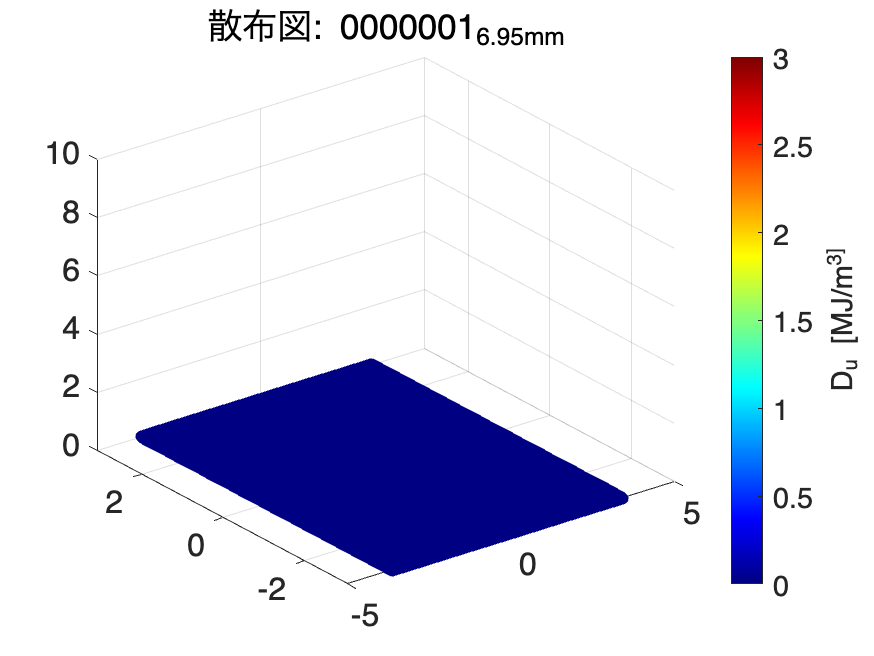

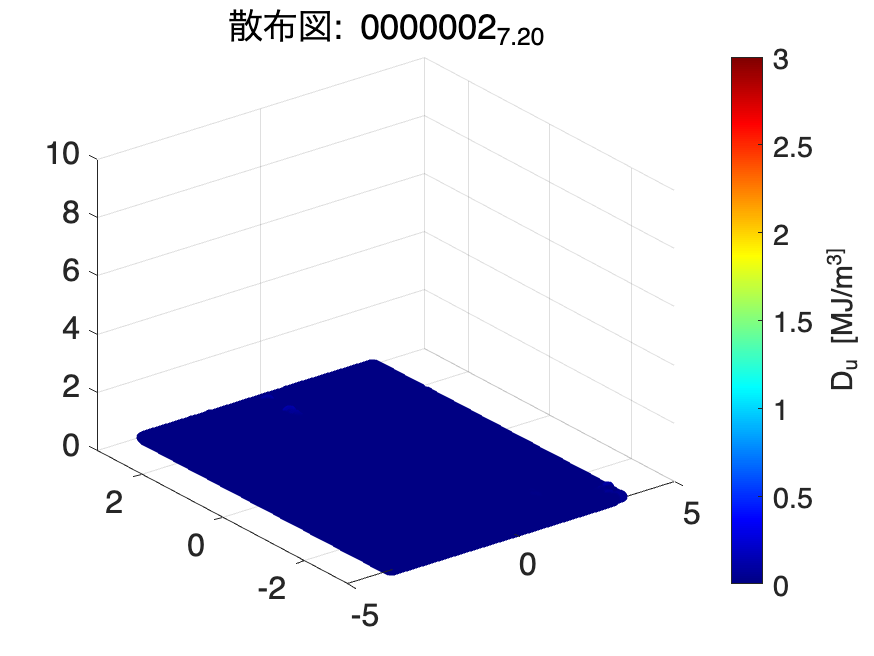

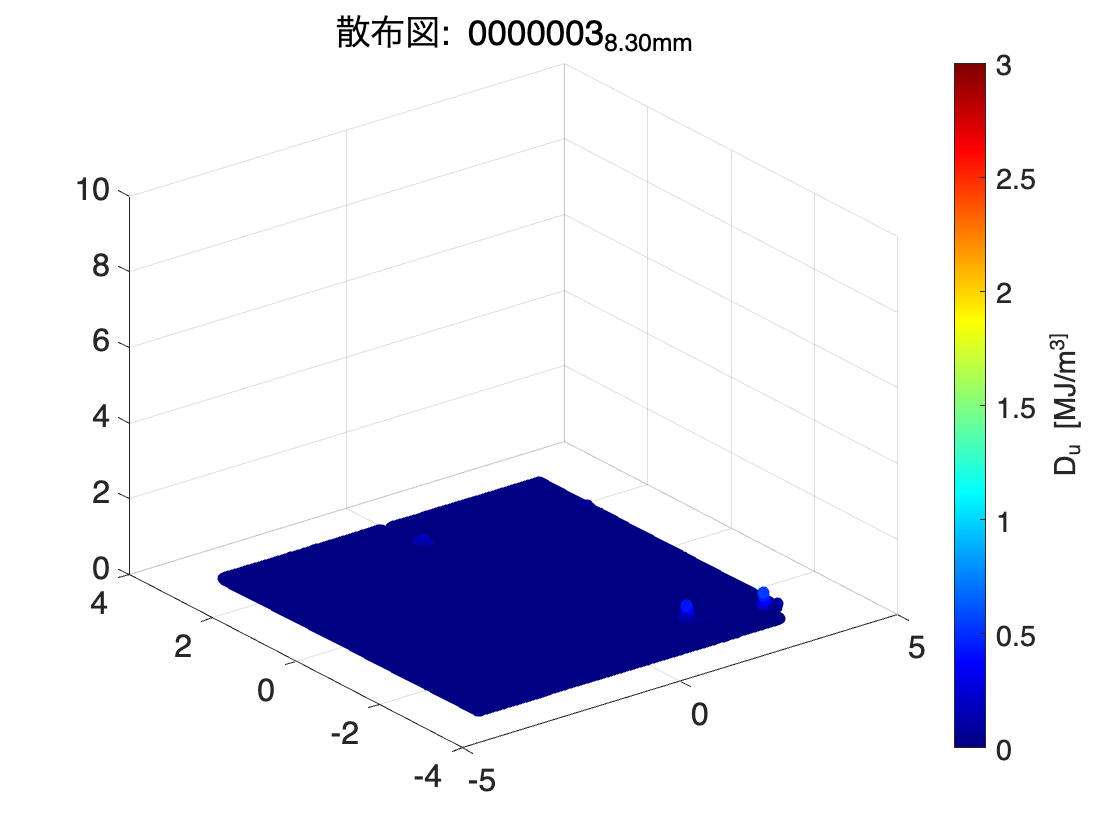

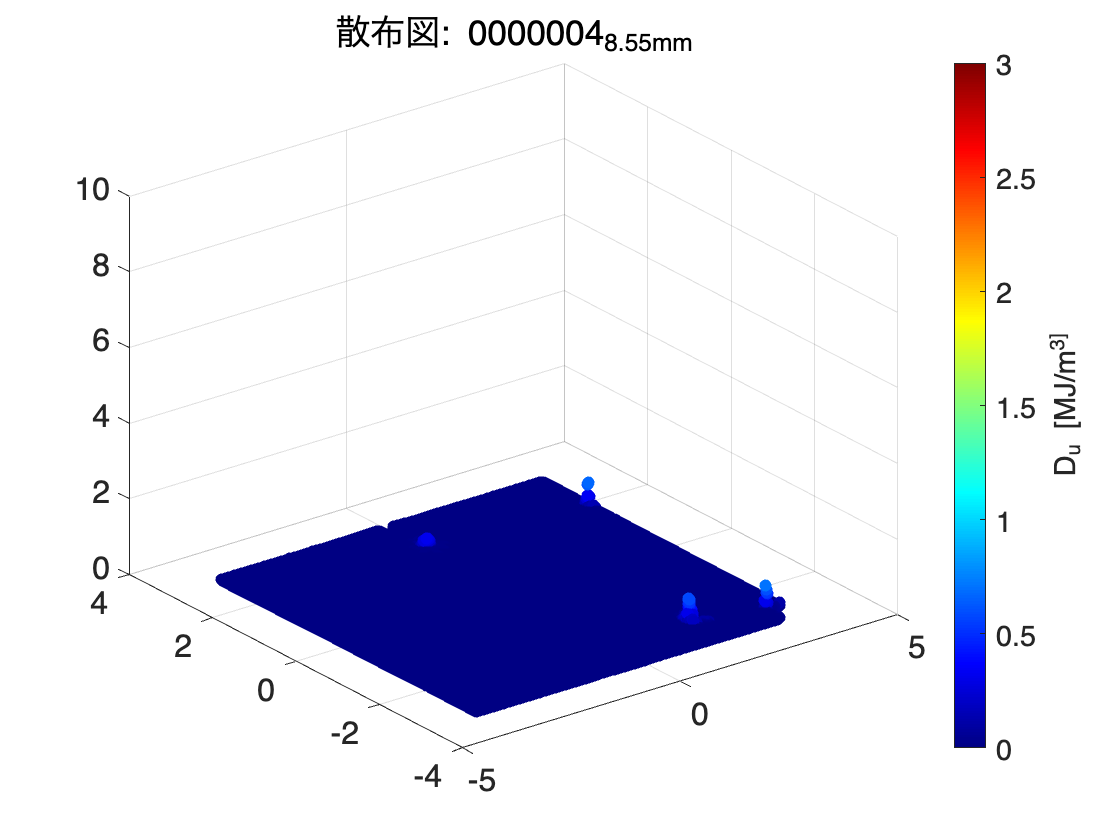

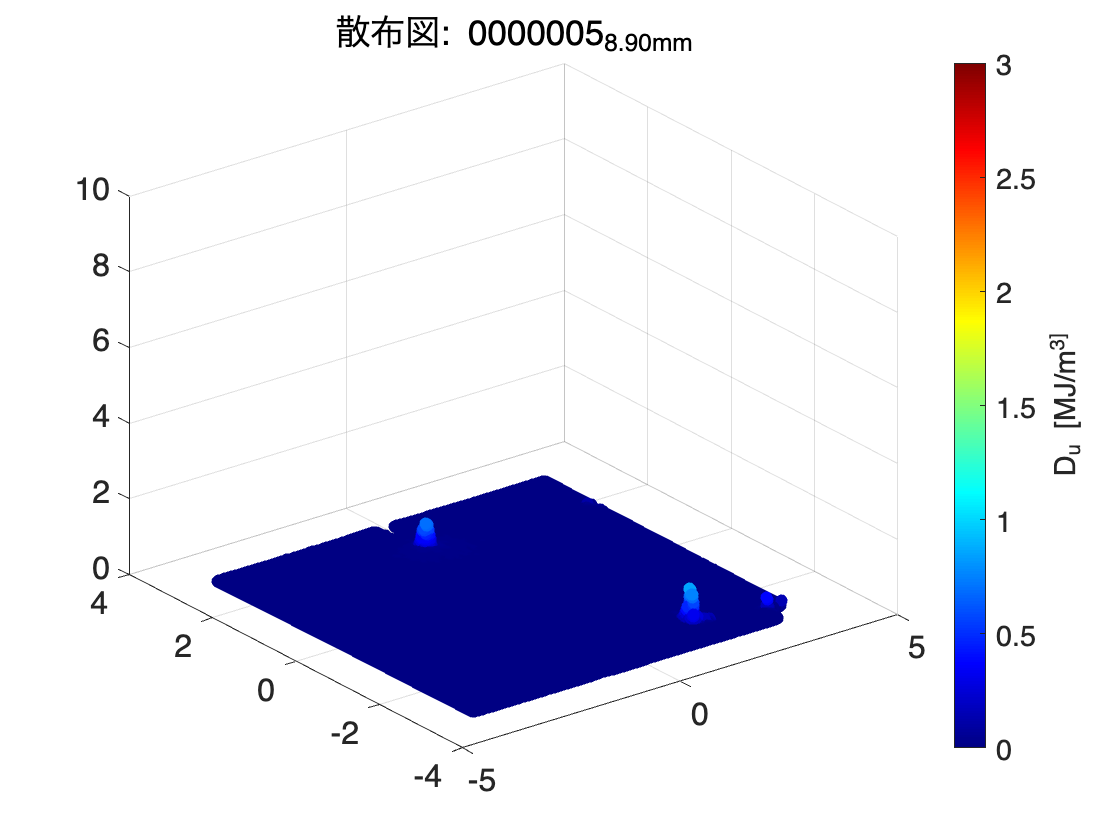

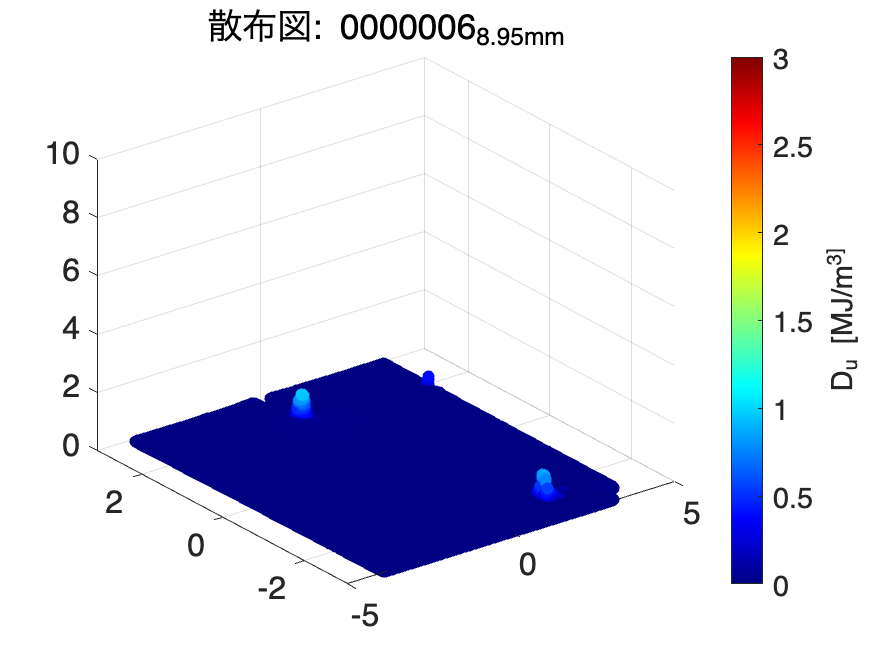

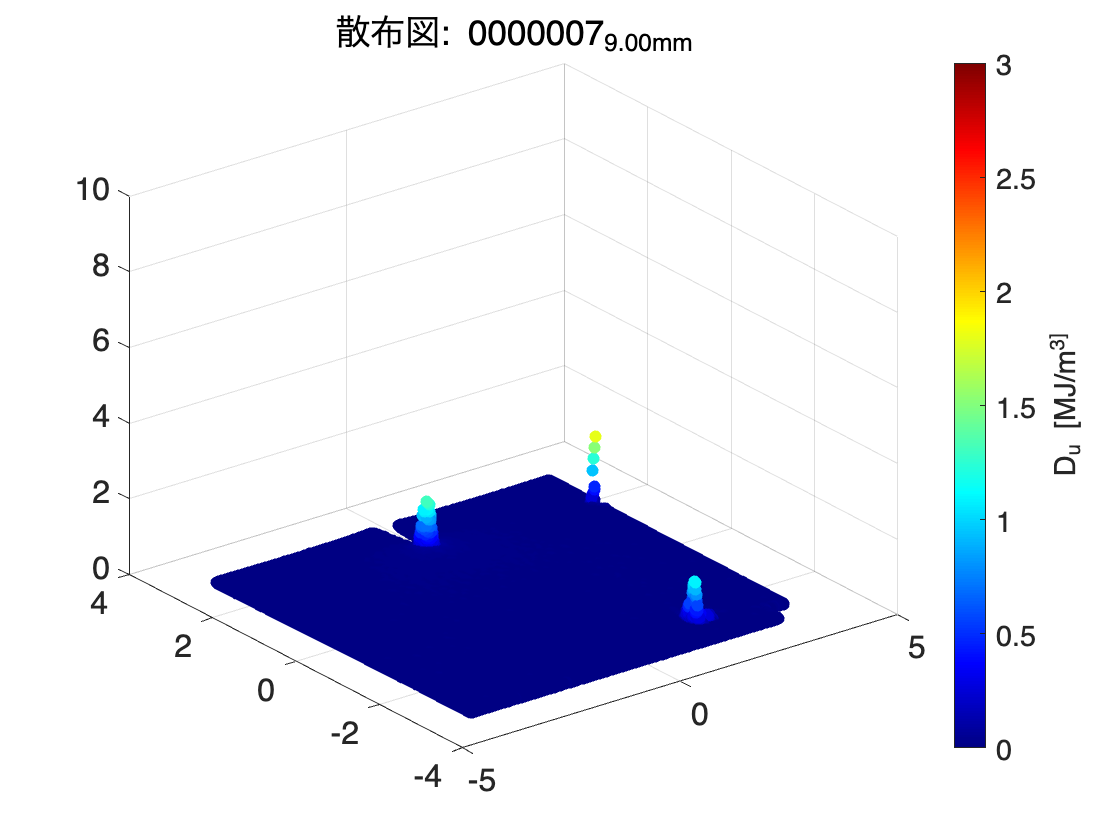

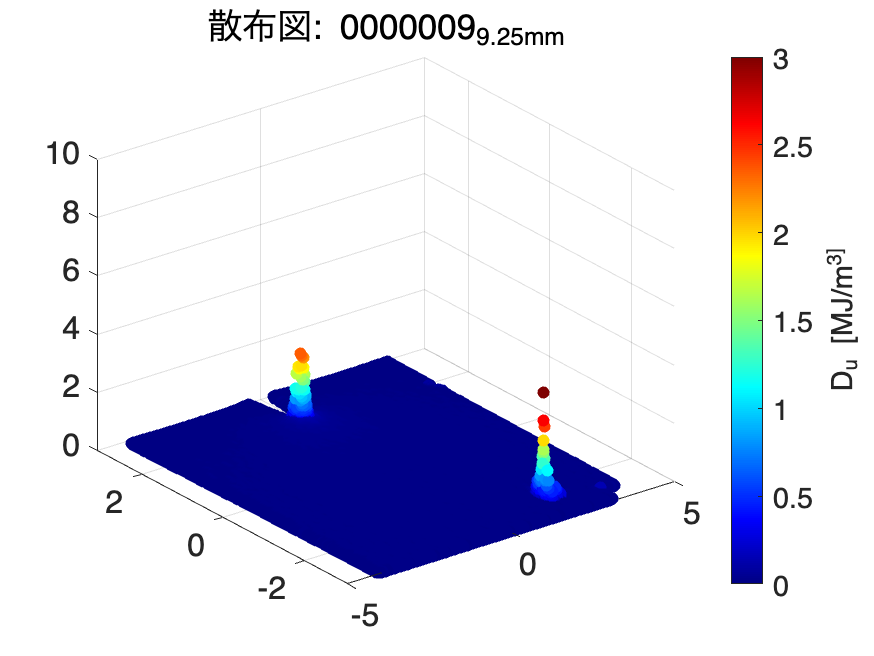


% ファイル数を取得
numFiles = numel(fileList);

% ループを使用して各CSVファイルについてプロットを行う

for i = 1:numFiles
    % ファイルのフルパスを取得
    filePath = fullfile(folderPath, fileList(i).name);
    
    % CSVファイルを読み込む
    %data = readmatrix(filePath);

    % 対応するcsvファイルの読み込み（readtableを使用）
    corresponding_csv = readtable(filePath);
    



    % n列目をx軸、m列目をy軸としてプロット
    %xData = data(:, N(1));
    %yData = data(:, N(2));

%         % 各座標の主ひずみを格納するための配列を初期化
%     principalStrain1 = zeros(height(corresponding_csv), 1);
%     principalStrain2 = zeros(height(corresponding_csv), 1);
% 
% % 各座標についてループ
% for j = 1:height(corresponding_csv)
%     % ひずみテンソルを作成
%     strainTensor = [corresponding_csv.exx(j), corresponding_csv.exy(j); corresponding_csv.exy(j), corresponding_csv.eyy(j)];
% 
%     % 固有値（主ひずみ）の計算
%     eigenValues = eig(strainTensor);
% 
%     % 主ひずみを配列に格納
%     principalStrain1(j) = eigenValues(1);
%     principalStrain2(j) = eigenValues(2);
% end
% 
%     % 結果をtableに追加
%     corresponding_csv.principalStrain1 = principalStrain1;
%     corresponding_csv.principalStrain2 = principalStrain2;

    xData = corresponding_csv.x_c + corresponding_csv.u_c; % 数値データの列名を適宜変更
    yData = corresponding_csv.y_c + corresponding_csv.v_c; % 数値データの列名を適宜変更


    pixel_values = 0.0702 .* (corresponding_csv.I_1 -3) + 0.3793 .* (corresponding_csv.I_2 -3) + 0.0118 .* (corresponding_csv.I_1 -3) .* (corresponding_csv.I_2 -3);   % データを画素値として取得


    % 新しい図を作成
    figure;

    % カラーマップを選択
    colormap(jet);


    % プロット
    scatter3(xData, yData, pixel_values, [], pixel_values, 'filled');
    h = colorbar;

    % % 軸のラベルを設定（必要に応じて）
    % xlabel('\epsilon_1');
    % ylabel('\epsilon_2');
    % 
    % カラーバーのラベルを設定
    colorbar_label = 'D_u [MJ/m^3]'; 
    ylabel(h, colorbar_label);
    % 
    % % カラーバーを設定
    clim([0, 3]);
    % 
    % 
    zlim([0, 10]);
    % ylim([-0.4, 0.8]);

    % グラフのタイトルを設定（ファイル名から取得）
    [~, file_name, ~] = fileparts(fileList(i).name);
    title(['散布図: ', file_name]);

    % フィギュアを保存（任意）
    saveas(gcf, ['scatter3DOfxvseyDu_', file_name, '.png']);
    
    
end

virginLoading, reLoading, unLoadingのプロットfunction

function output = plotdata2D(A, c, N)
% CSVファイルが保存されているフォルダのパスを指定
folderPath = A;

% フォルダ内のCSVファイルのリストを取得
fileList = dir(fullfile(folderPath, '*.csv'))

% ファイル数を取得
numFiles = numel(fileList)

% ループを使用して各CSVファイルについてプロットを行う
k = 0 % kの初期化
for i = 1:ceil(numFiles/2)
    % ファイルのフルパスを取得
    filePath = fullfile(folderPath, fileList(i).name);
    
    % CSVファイルを読み込む
    data = readmatrix(filePath);

    % n列目をx軸、m列目をy軸, o列目をz軸としてプロット
    xData = data(k + 1:end, N(1));
    yData = data(k + 1:end, N(2));

    % プロット
    
    scatter(xData, yData, c, "r", 'filled')
    

    if k > 0
    % n列目をx軸、m列目をy軸, o列目をz軸としてプロット
    xData = data(1:k, N(1));
    yData = data(1:k, N(2));
    
    end

    k = numel(data(:, 1)) % kの更新

    % プロット
    hold on
    scatter(xData, yData, c, "b", 'filled')
    hold off
end

% ループを使用して各CSVファイルについてプロットを行う
for i = ceil(numFiles/2) + 1 : numFiles
    % ファイルのフルパスを取得
    filePath = fullfile(folderPath, fileList(i).name);
    
    % CSVファイルを読み込む
    data = readmatrix(filePath);
    
    % n列目をx軸、m列目をy軸, o列目をz軸としてプロット
    xData = data(:, N(1));
    yData = data(:, N(2));
    

    % プロット
    hold on
    scatter(xData, yData, c, "k", 'filled')
    hold off
end

end